%Solution 1
%Unit step response

syms s
C = ((s-1.962)*(s+1.131))/(s*(s-41.625))

$$C = \frac{\left(s-\frac{981}{500}\right)\,\left(s+\frac{1131}{1000}\right)}{s\,\left(s-\frac{333}{8}\right)}$$

P = (5*s-5)/((s+1)*(s-5))

$$P = \frac{5\,s-5}{\left(s+1\right)\,\left(s-5\right)}$$

CLTF = (C*P)/(1+C*P)

$$CLTF = \frac{\left(5\,s-5\right)\,\left(s-\frac{981}{500}\right)\,\left(s+\frac{1131}{1000}\right)}{s\,\left(s+1\right)\,\left(s-5\right)\,\left(s-\frac{333}{8}\right)\,\left(\frac{\left(5\,s-5\right)\,\left(s-\frac{981}{500}\right)\,\left(s+\frac{1131}{1000}\right)}{s\,\left(s+1\right)\,\left(s-5\right)\,\left(s-\frac{333}{8}\right)}+1\right)}$$

R = 1/s

$$R = \frac{1}{s}$$

Y =CLTF*R

$$Y = \frac{\left(5\,s-5\right)\,\left(s-\frac{981}{500}\right)\,\left(s+\frac{1131}{1000}\right)}{s^{2}\,\left(s+1\right)\,\left(s-5\right)\,\left(s-\frac{333}{8}\right)\,\left(\frac{\left(5\,s-5\right)\,\left(s-\frac{981}{500}\right)\,\left(s+\frac{1131}{1000}\right)}{s\,\left(s+1\right)\,\left(s-5\right)\,\left(s-\frac{333}{8}\right)}+1\right)}$$

y = ilaplace(Y)

$$y = \begin{array}{l} 4562500\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)-20812500\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{\sigma_{1}}\right)-16150000\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{30469000\,\sigma_{2}-12187500\,{\sigma_{2}}^{2}+400000\,{\sigma_{2}}^{3}+20118489}\right)-100000\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{3}}{\sigma_{1}}\right)+1\\ \mathrm{where}\\ \sigma_{1}=400000\,{\sigma_{2}}^{3}-12187500\,{\sigma_{2}}^{2}+30469000\,\sigma_{2}+20118489\\ \sigma_{2}=\mathrm{root}\left(z^{4}-\frac{325\,z^{3}}{8}+\frac{30469\,z^{2}}{200}+\frac{20118489\,z}{100000}+\frac{1109511}{100000},z,k\right) \end{array}$$


t = 8

t = 8

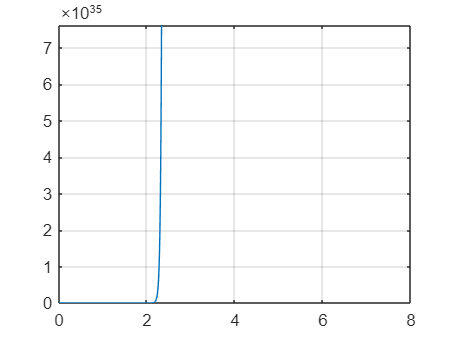

fplot(y,[0 t])
grid on